clc; clear; close all; addpath z_toolbox; 
load(fullfile("step5_IEDxcorr_TD-6d0_IT-100ms_fitting", ...
    "op3_fibN-vs-xcD_fitting.mat"), 'fibNas', 'xcDas');
x = fibNas; y = xcDas;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.4300

     0



figure('Units', 'centimeters', 'Position', [5, 5, 26, 20]);
subplot(4, 2, 1);
f_densityScatter(x, y, 1);
hold on;
[~, ~, ~, Curve] = fit_polyfit(x, y, 1, 0.05);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('SC Strength'); 
ylabel('IED Lagged-Corr Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile("step5_IEDxcorr_TD-6d0_IT-100ms_fitting", ...
    "op3_fibN-vs-xcD_fitting.mat"), 'fibNres_as', 'xcDres_as');
x = fibNres_as; y = xcDres_as;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.0745

   2.7168e-35



subplot(4, 2, 2);
f_densityScatter(x, y, 1);
hold on;
[~, ~, ~, Curve] = fit_polyfit(x, y, 1, 0.05);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('SC Strength'); 
ylabel('IED Lagged-Corr Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile("step6_NAxcorr_TD-6d0_IT-100ms_fitting", ...
    "op3_NAxcorr_fibN-vs-xcD_fitting.mat"), 'fibNas', 'xcDas');
x = fibNas; y = xcDas;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.4391

     0



subplot(4, 2, 3);
f_densityScatter(x, y, 1);
hold on;
[~, ~, ~, Curve] = fit_polyfit(x, y, 1, 0.05);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('SC Strength'); 
ylabel('Normal-Activity Lagged-Corr Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile("step6_NAxcorr_TD-6d0_IT-100ms_fitting", ...
    "op3_NAxcorr_fibN-vs-xcD_fitting.mat"), 'fibNres_as', 'xcDres_as');
x = fibNres_as; y = xcDres_as;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.0824

   6.8145e-43



subplot(4, 2, 4);
f_densityScatter(x, y, 1);
hold on;
[~, ~, ~, Curve] = fit_polyfit(x, y, 1, 0.05);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('SC Strength'); 
ylabel('Normal-Activity Lagged-Corr Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
clc; clear; 
load(fullfile('step5_IEDxcorr_TD-6d0_IT-100ms_fitting', ...
    'op3_fibN-vs-xcD_fitting.mat'));
nS = 13; subID = 'sub-0014';
xcD = fibN_xcD_corr(nS).xcD;
fibN = fibN_xcD_corr(nS).fibN;
nBins = 20; minPerBinTarget = 20; 
for tryBins = nBins:-1:5
    edges = linspace(min(xcD), max(xcD), tryBins+1);
    binID = discretize(xcD, edges);
    counts = accumarray(binID(~isnan(binID)), 1, [tryBins 1], @sum, 0);
    validBins = find(counts > 0);
    if isempty(validBins); continue; end
    nPerBin = min(counts(validBins));
    if nPerBin >= minPerBinTarget
        nBins = tryBins;
        break;
    end
end
% Recompute with final nBins
edges = linspace(min(xcD), max(xcD), nBins+1);
binID = discretize(xcD, edges);
counts = accumarray(binID(~isnan(binID)), 1, [nBins 1], @sum, 0);
validBins = find(counts > 0);
nPerBin = min(counts(validBins));
sel = false(size(xcD));
for b = validBins(:)'
    idxB = find(binID == b);
    % sample exactly nPerBin from each bin
    pick = idxB(randperm(numel(idxB), nPerBin));
    sel(pick) = true;
end
xcD_u  = xcD(sel); fibN_u = fibN(sel);
x = fibN_u; y = xcD_u;
[r, p] = corr(x, y, "type", "Spearman");
% [r, p] = corr(x, y, "type", "Pearson");
[~, ~, ~, Curve] = fit_polyfit(x, y, 1, 0.05);
disp(r); disp(p);

   -0.5318

   6.3362e-19



subplot(4, 2, 5);
f_densityScatter(x, y, 1); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('SC Strength'); ylabel('IED Lagged-Corr Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step5_IEDxcorr_TD-6d0_IT-100ms_fitting', ...
    'op6_fibN-vs-xcD_fitting_uniformResample.mat'));
disp(rho_uniform_mean(13));disp(rho_uniform_std(13));

   -0.5179

    0.0306



idx = find(rho_uniform_mean~=0);
R = rho_uniform_mean(idx);
% violin plot
Rstr = {};
for n = 1:length(idx)
    Rstr{n, 1} = 'SC Strength vs. Delay';
end
subplot(4, 2, 6);
vs = violinplot(R', Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2,'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 1.5]); ylim([-0.7, 0.1]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step6_NAxcorr_TD-6d0_IT-100ms_fitting', ...
    'op3_NAxcorr_fibN-vs-xcD_fitting.mat'));
nS = 13; subID = 'sub-0014';
xcD = fibN_xcD_corr(nS).xcD;
fibN = fibN_xcD_corr(nS).fibN;
nBins = 20; minPerBinTarget = 20; 
for tryBins = nBins:-1:5
    edges = linspace(min(xcD), max(xcD), tryBins+1);
    binID = discretize(xcD, edges);
    counts = accumarray(binID(~isnan(binID)), 1, [tryBins 1], @sum, 0);
    validBins = find(counts > 0);
    if isempty(validBins); continue; end
    nPerBin = min(counts(validBins));
    if nPerBin >= minPerBinTarget
        nBins = tryBins;
        break;
    end
end
% Recompute with final nBins
edges = linspace(min(xcD), max(xcD), nBins+1);
binID = discretize(xcD, edges);
counts = accumarray(binID(~isnan(binID)), 1, [nBins 1], @sum, 0);
validBins = find(counts > 0);
nPerBin = min(counts(validBins));
sel = false(size(xcD));
for b = validBins(:)'
    idxB = find(binID == b);
    % sample exactly nPerBin from each bin
    pick = idxB(randperm(numel(idxB), nPerBin));
    sel(pick) = true;
end
xcD_u  = xcD(sel); fibN_u = fibN(sel);
x = fibN_u; y = xcD_u;
[r, p] = corr(x, y, "type", "Spearman");
% [r, p] = corr(x, y, "type", "Pearson");
[~, ~, ~, Curve] = fit_polyfit(x, y, 1, 0.05);
disp(r); disp(p);

   -0.4518

   1.4223e-13



subplot(4, 2, 7);
f_densityScatter(x, y, 1); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('SC Strength'); 
ylabel('Normal-Activity Lagged-Corr Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step6_NAxcorr_TD-6d0_IT-100ms_fitting', ...
    'op7_fibN-vs-xcD_fitting_uniformResample.mat'));
disp(rho_uniform_mean(13));disp(rho_uniform_std(13));

   -0.4824

    0.0364



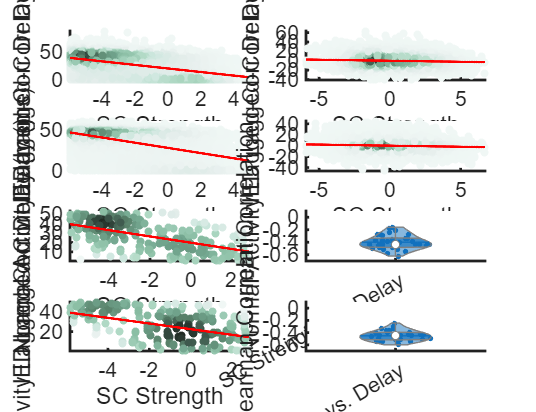

idx = find(rho_uniform_mean~=0);
R = rho_uniform_mean(idx);
% violin plot
Rstr = {};
for n = 1:length(idx)
    Rstr{n, 1} = 'SC Strength vs. Delay';
end
subplot(4, 2, 8);
vs = violinplot(R', Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2,'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 1.5]); ylim([-0.7, 0.1]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);